clc
clear
close all

Init quadrotor

initQuadrotorData(0,0,0,0);

Mode = 1;
x0=0;
y0=0;
z0=0;
phi0=0;
theta0=0;
psi0=0;

forward_1 = 20;
forward_2 = 20;
up_down = 5;
total_time = 60;



    
base_path = pwd+"\images\";
LQR_1_path = base_path+"LQR_1\";
LQR_2_path = base_path+"LQR_2\";
MPC_1_path = base_path+"MPC_1\";
results = [];

%%% Run model LQR
if Mode==1
    time_model_arr=[40;40;40;30;30;30];
else
    time_model_arr=[60;60;60;30;30;30];
end
c_a_arr = [0;0.01;0.1;];
C_drag_arr = [0;0.1;0.1];
c_b_arr = [0;0;0.1];
c_d_arr = [0;0.01;0.1];
ITERATIONS = 3;

Qc = diag([1 1 1 0 0 0 10 10 1 0 0 0])*10;
Rc = diag([1, 1, 1, 1]);
if Mode==1
    prefixes = {'eight_no_ressist', 'eight_small_resist', 'eight_normal_resist'};
else
    prefixes = {'fig_no_ressist', 'fig_small_resist', 'fig_normal_resist'};
end
[K, ~, ~] = lqr(A, B, Qc, Rc);
disp('LQR 1 коэффициенты регулятора:');

LQR 1 коэффициенты регулятора:


disp(K);

   -0.0000   -0.0000    3.1623    0.0000   -0.0000    2.0276    0.0000    0.0000   -0.0000   -0.0000    0.0000   -0.0000
    0.0000   -3.1623   -0.0000    0.0000   -2.6054   -0.0000   10.5184    0.0000    0.0000    0.2109    0.0000    0.0000
    3.1623   -0.0000   -0.0000    2.6054   -0.0000    0.0000    0.0000   10.5184   -0.0000    0.0000    0.2109   -0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    3.1623   -0.0000    0.0000    0.1652




Квадратичный критерий J = 2577.2721

--- Оценка слежения за траекторией ---
MAE (r_x, r_y, r_z): 1.0144, 0.6545, 0.1829
RMSE (r_x, r_y, r_z): 1.1406, 0.7385, 0.8630
MSE (r_x, r_y, r_z): 1.3010, 0.5454, 0.7448
Mean Error (r_x, r_y, r_z): -0.2137, 0.0236, -0.1727
Перерегулирование (%): 1.06, 447.43, 3.90


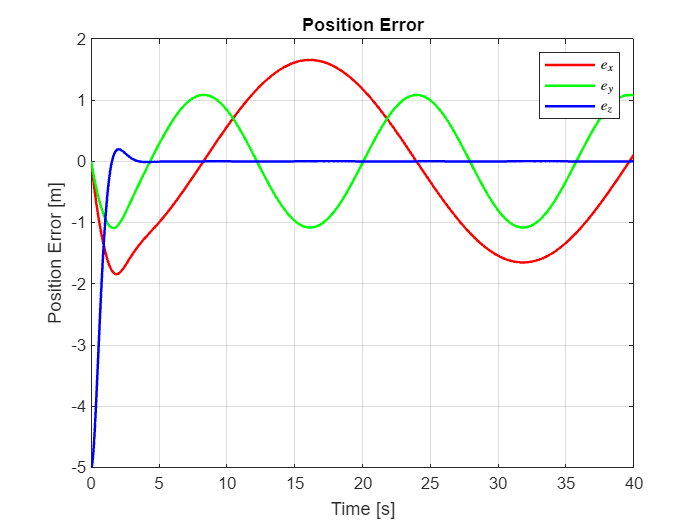

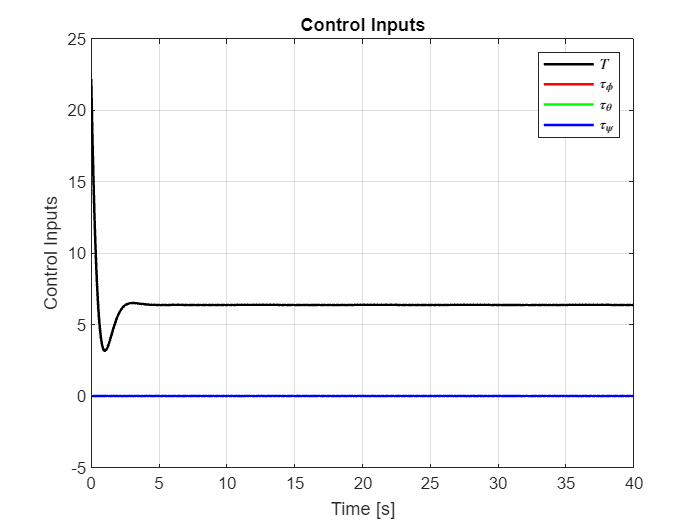

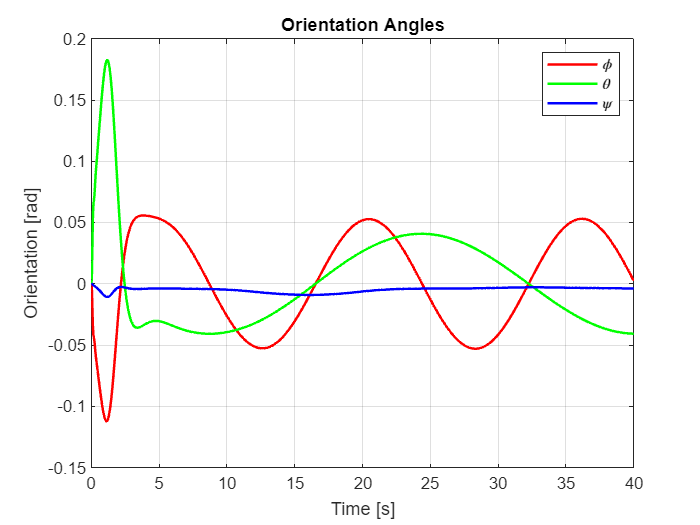

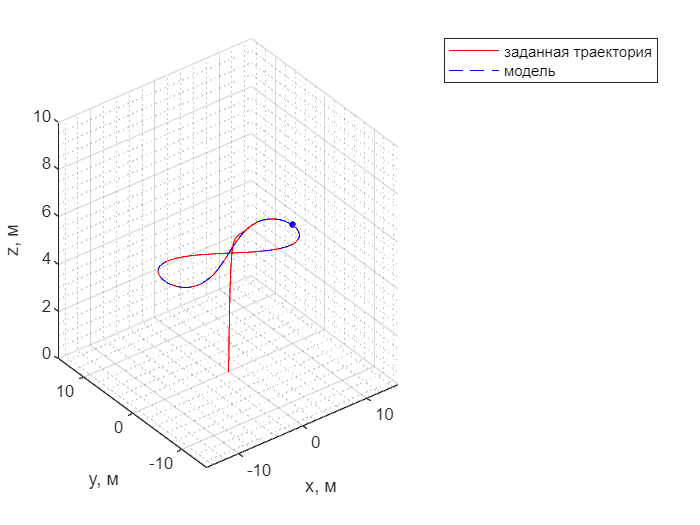


Квадратичный критерий J = 2696.3394

--- Оценка слежения за траекторией ---
MAE (r_x, r_y, r_z): 1.0954, 0.6994, 0.1832
RMSE (r_x, r_y, r_z): 1.2297, 0.7888, 0.8625
MSE (r_x, r_y, r_z): 1.5122, 0.6221, 0.7439
Mean Error (r_x, r_y, r_z): -0.2309, 0.0196, -0.1736
Перерегулирование (%): 0.83, 443.95, 3.72


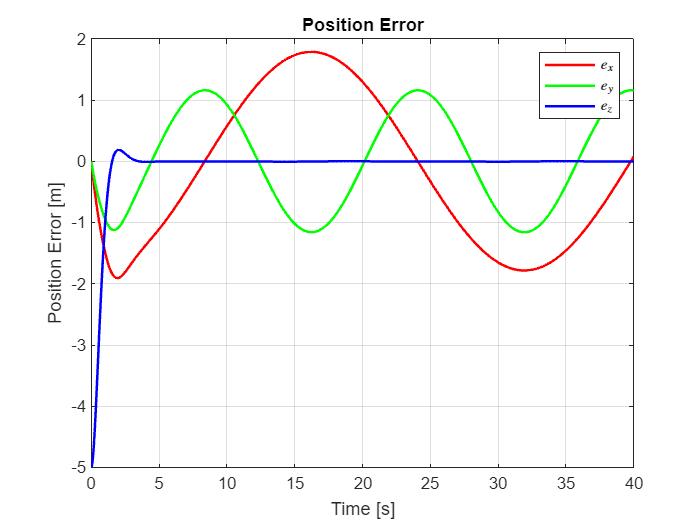

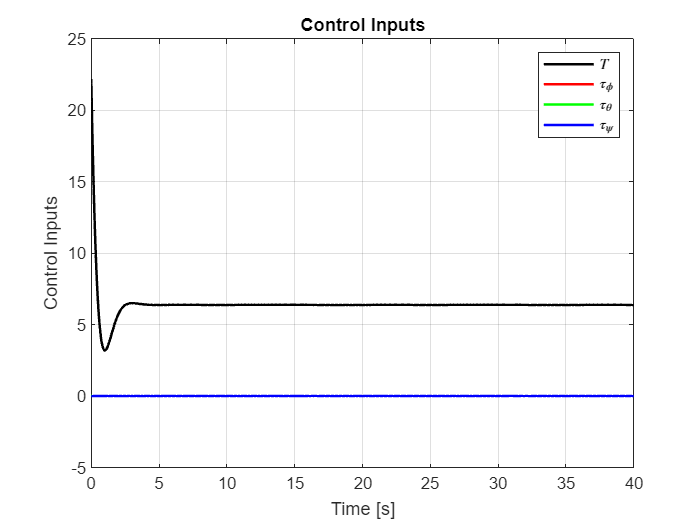

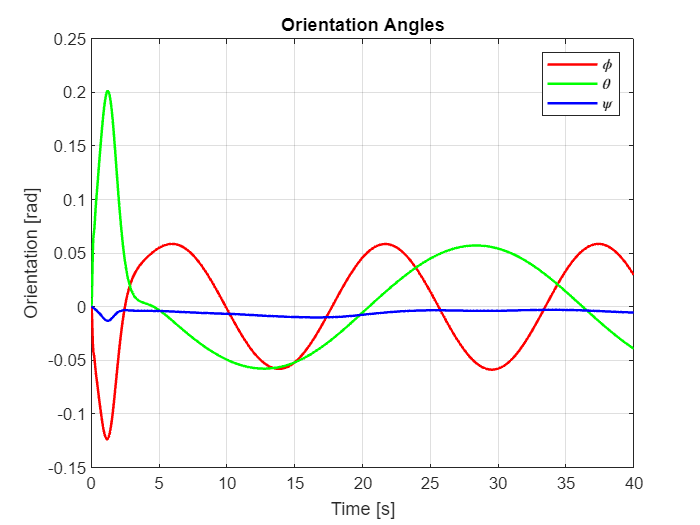

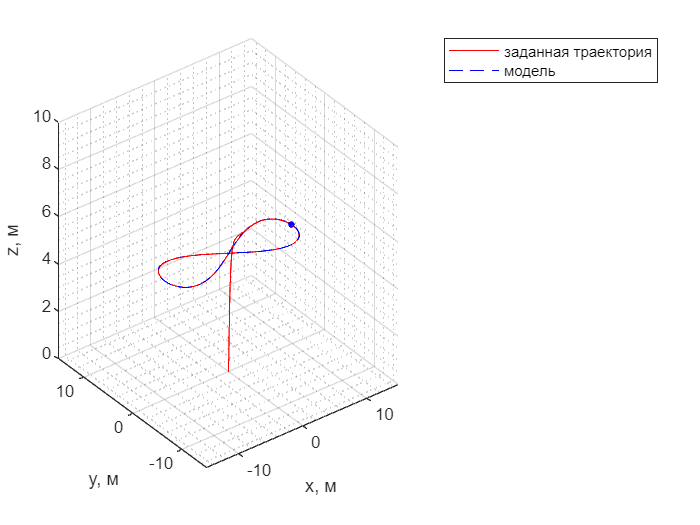


Квадратичный критерий J = 4520.5222

--- Оценка слежения за траекторией ---
MAE (r_x, r_y, r_z): 1.8866, 1.0749, 0.3146
RMSE (r_x, r_y, r_z): 2.1085, 1.2304, 0.8799
MSE (r_x, r_y, r_z): 4.4457, 1.5138, 0.7742
Mean Error (r_x, r_y, r_z): -0.3861, 0.0748, -0.3116
Перерегулирование (%): 0.08, 459.66, 2.16


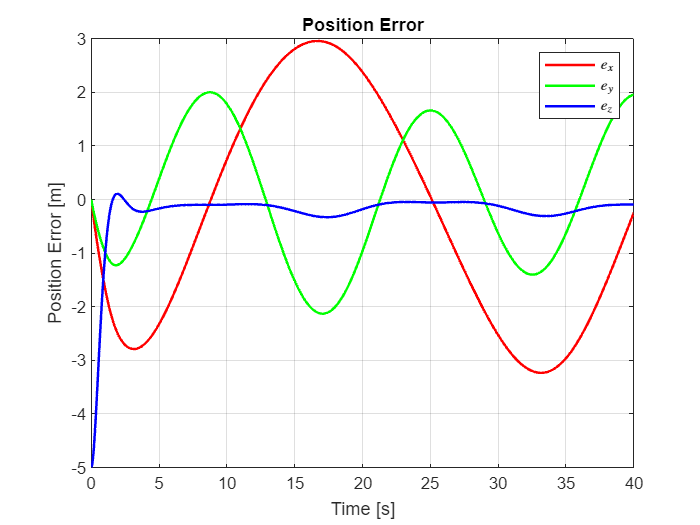

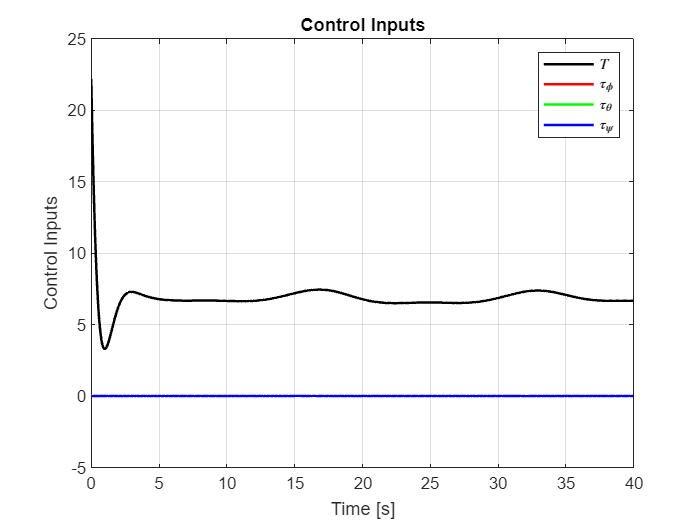

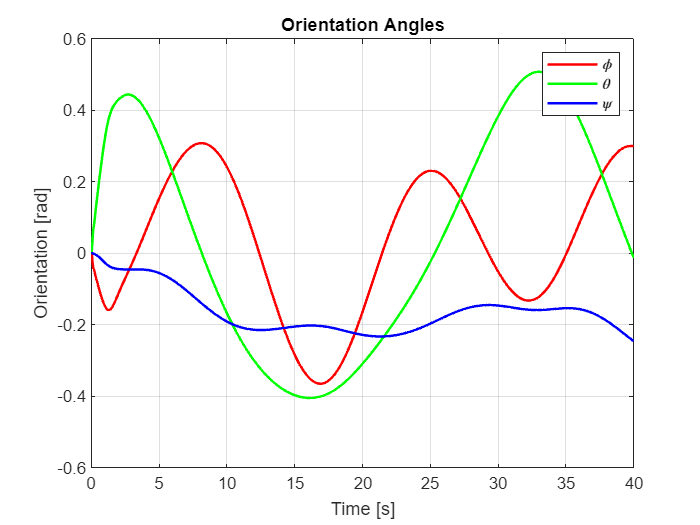

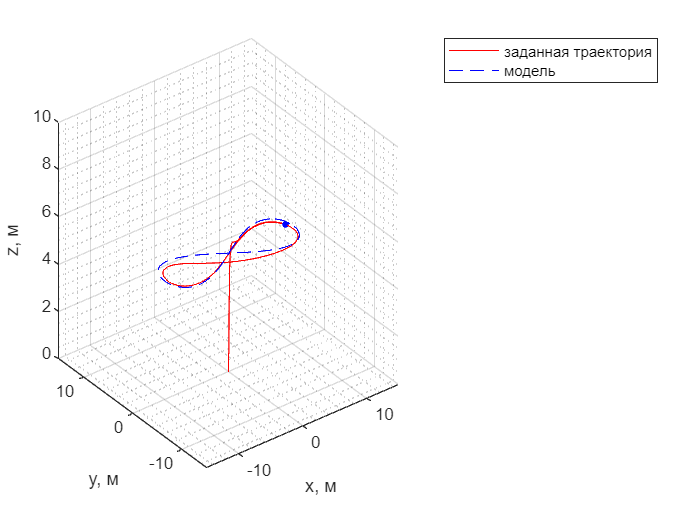

LQR_1_X = {};
LQR_1_Y = {};
LQR_1_Z = {};
for i=1:ITERATIONS
    C_drag = C_drag_arr(i);
    c_a = c_a_arr(i);
    c_b = c_b_arr(i);
    c_d = c_d_arr(i);
    initQuadrotorData(c_a,c_b,c_d,C_drag);
    time_model=time_model_arr(i);
    
    Simulation = sim('LQR_1_QuadrotorModel.slx');
    LQR_1_X{i} = Simulation.x.Data;
    LQR_1_Y{i} = Simulation.y.Data;
    LQR_1_Z{i} = Simulation.z.Data;
    %Simulation = sim('model_for_testing_errors.slx');
    f = figure;
    plot3(Simulation.x.Data, Simulation.y.Data, Simulation.z.Data, 'r');
    hold on
    plot3(Simulation.trajectory.Data(1,:),Simulation.trajectory.Data(2,:),Simulation.trajectory.Data(3,:),'b--')
    %plot3(Simulation.x1.Data, Simulation.y1.Data, Simulation.z1.Data, 'g--');
    if Mode==1
        xlim([-15, 15])
        ylim([-15, 15])
        zlim([0, 10])
    else
        xlim([-1, 21])
        ylim([-21, 1])
        zlim([0, 6])
    end
    grid on
    grid minor
    scatter3(Simulation.x.Data(end), Simulation.y.Data(end), Simulation.z.Data(end),15,'filled', 'b')
    xlabel("x, м")
    ylabel("y, м")
    zlabel("z, м")
    legend({"заданная траектория", "модель"})
    %title("Движение по траектории "+ graphic_names[Mode])
    grid on
    ax = gca;
    X = Simulation.X.Data;
    Xd = squeeze(Simulation.trajectory.Data)';
    U = Simulation.U.Data;
    t = Simulation.U.Time;
    Qm = Qc(1:3, 1:3);
    Rm = Rc;
    metrics = evaluateTrajectoryTrackingMetrics(X, Xd, U, t, Qm, Rm);
    pref =  prefixes{i};
    metrics.name = "LQR_1_"+string(pref);
    results = [results; metrics];
    pref =  prefixes{i};
    plotQuadrotorData(X, Xd, U, t, LQR_1_path, pref)
    ax.GridColor = [0, 0, 0];  % [R, G, B]
    
end


Ax = [0 1; 0 0];    % одинаково для всех осей
Bx = [0; 1];

% Весовые матрицы
% % Позиции
% Q_pos = [4e2 0; 0 1];  % x, y, z
% R_pos = 1;
% 
% % Углы (фи, тета, пси)
% Q_ang = [1e10 0; 0 1];   % phi, theta, psi
% R_ang = 1;
% % Вычисление матрицы коэффициентов регулятор
% Kx = lqr(Ax, Bx, Q_pos, R_pos);
% Ky = lqr(Ax, Bx, Q_pos, R_pos);
% Kz = lqr(Ax, Bx, Q_pos/10, R_pos);
% 
% Kphi   = lqr(Ax, Bx, Q_ang, R_ang);
% Ktheta = lqr(Ax, Bx, Q_ang, R_ang);
% Kpsi   = lqr(Ax, Bx, Q_ang/1e10, R_ang);


Q_pos = [1e2 0; 0 1];  % x, y, z
R_pos = 1;

% Углы (фи, тета, пси)
Q_ang = [1e8 0; 0 1];   % phi, theta, psi
R_ang = 1;
% Вычисление матрицы коэффициентов регулятор
Kx = lqr(Ax, Bx, Q_pos, R_pos);
Ky = lqr(Ax, Bx, Q_pos, R_pos);
Kz = lqr(Ax, Bx, Q_pos/10, R_pos);

Kphi   = lqr(Ax, Bx, Q_ang, R_ang);
Ktheta = lqr(Ax, Bx, Q_ang, R_ang);
Kpsi   = lqr(Ax, Bx, Q_ang/1e10, R_ang);


K = [Kx;Ky;Kz;Kphi;Ktheta;Kpsi];

disp('LQR 2  Feedback коэффициенты регулятора:');

LQR 2  Feedback коэффициенты регулятора:



disp(K);

   1.0e+04 *

    0.0010    0.0005
    0.0010    0.0005
    0.0003    0.0003
    1.0000    0.0141
    1.0000    0.0141
    0.0000    0.0000




Квадратичный критерий J = 2069.2681

--- Оценка слежения за траекторией ---
MAE (r_x, r_y, r_z): 0.5312, 0.3852, 0.2623
RMSE (r_x, r_y, r_z): 0.6028, 0.4337, 1.0040
MSE (r_x, r_y, r_z): 0.3634, 0.1881, 1.0081
Mean Error (r_x, r_y, r_z): -0.1059, 0.0175, -0.2511
Перерегулирование (%): 1.04, 447.25, 4.00


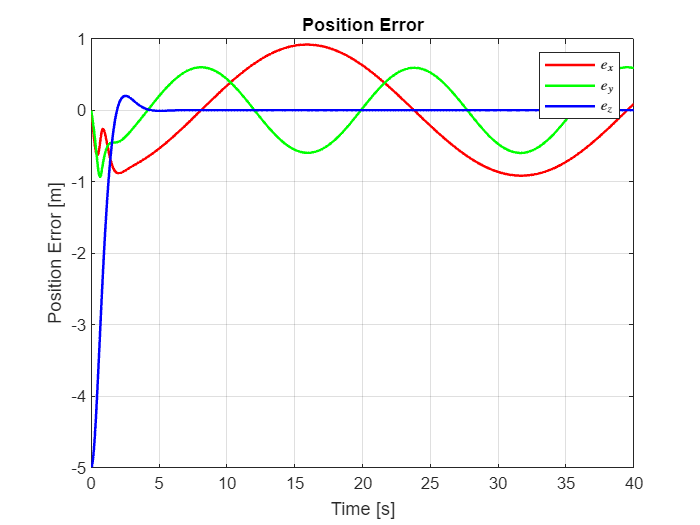

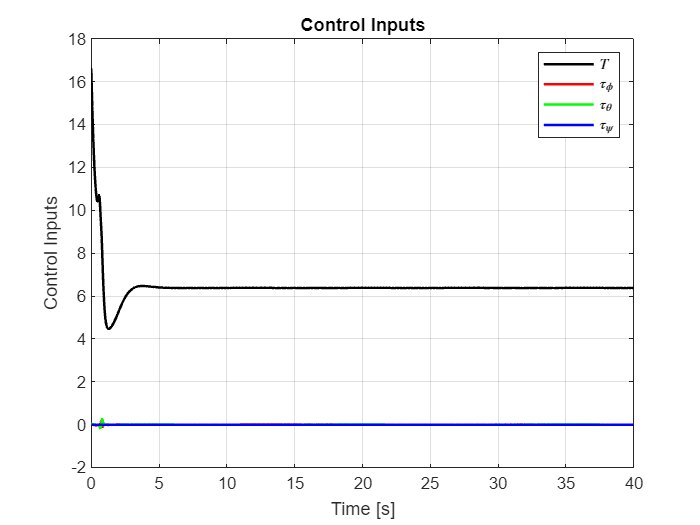

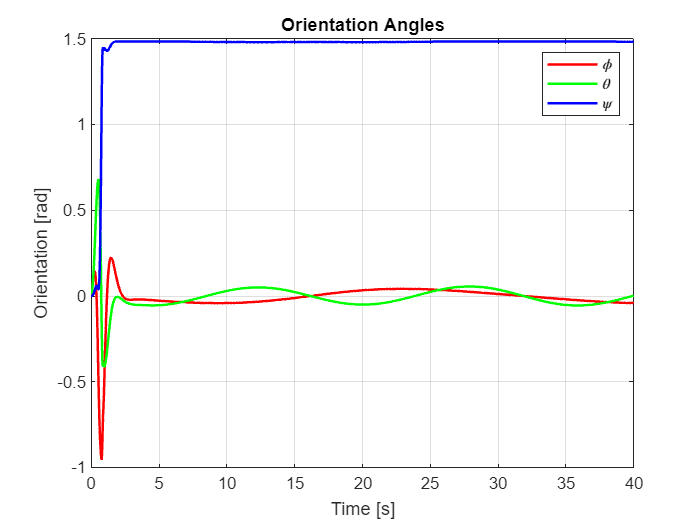

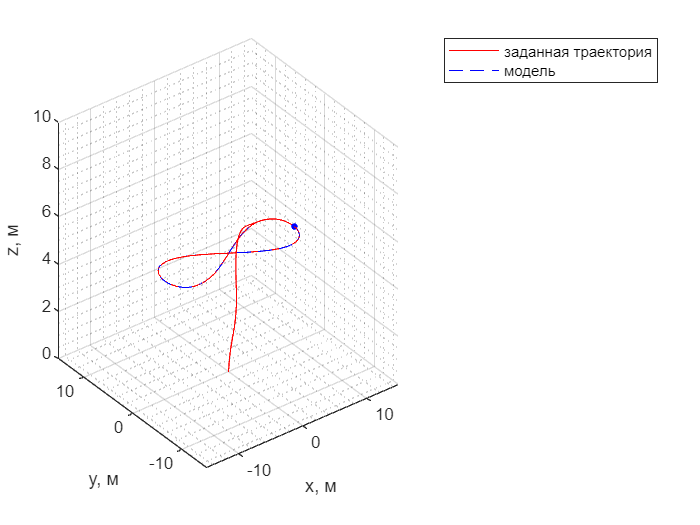


Квадратичный критерий J = 2088.6666

--- Оценка слежения за траекторией ---
MAE (r_x, r_y, r_z): 0.5544, 0.3993, 0.2554
RMSE (r_x, r_y, r_z): 0.6283, 0.4495, 0.9905
MSE (r_x, r_y, r_z): 0.3948, 0.2020, 0.9811
Mean Error (r_x, r_y, r_z): -0.1123, 0.0206, -0.2440
Перерегулирование (%): 0.95, 446.54, 3.96


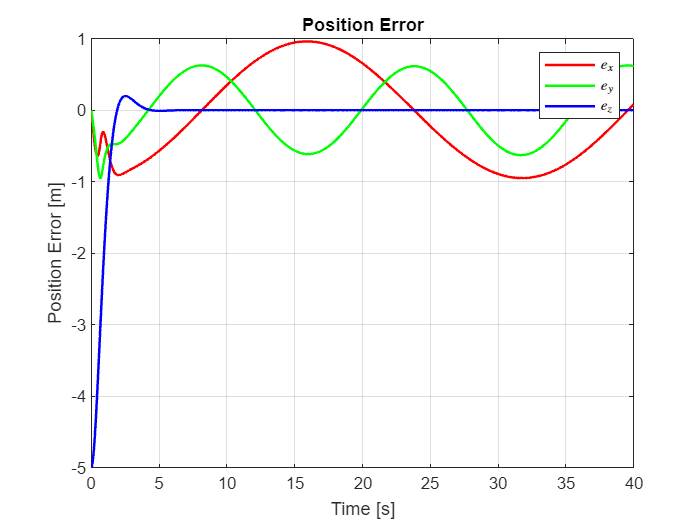

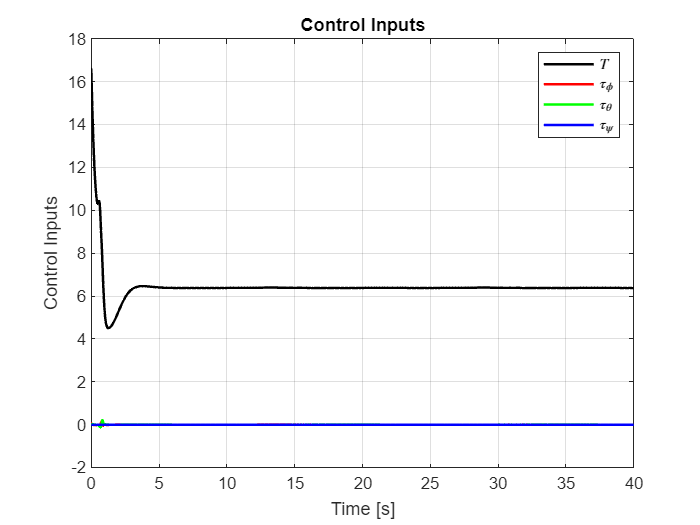

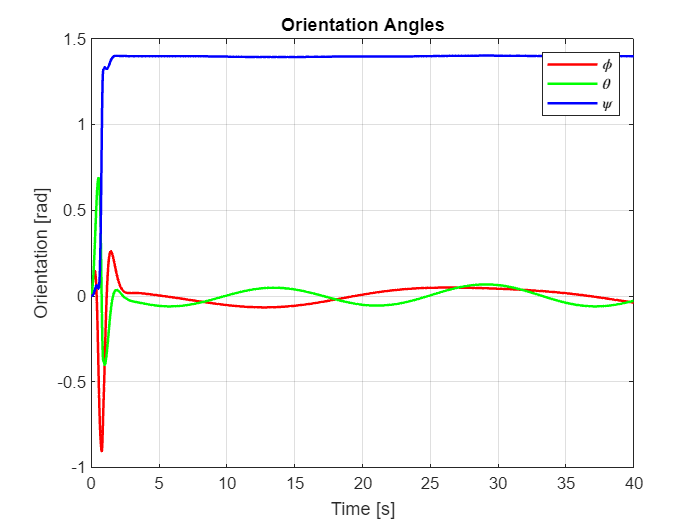

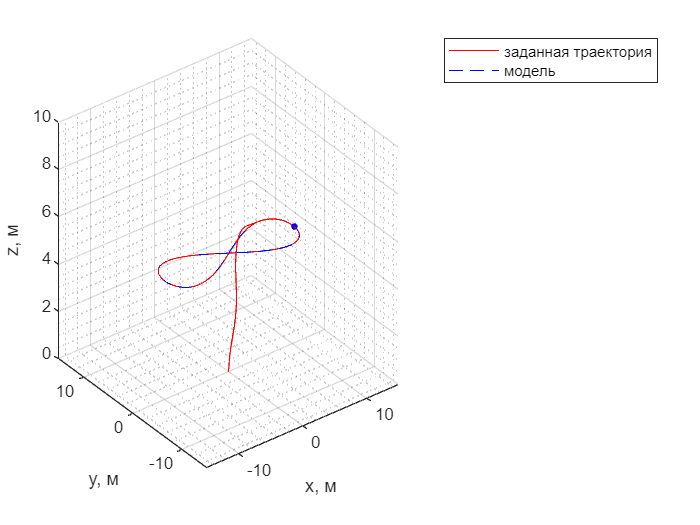


Квадратичный критерий J = 2516.5883

--- Оценка слежения за траекторией ---
MAE (r_x, r_y, r_z): 0.7517, 0.5106, 0.2113
RMSE (r_x, r_y, r_z): 0.8339, 0.5949, 0.8937
MSE (r_x, r_y, r_z): 0.6954, 0.3539, 0.7987
Mean Error (r_x, r_y, r_z): -0.1824, -0.0222, -0.1976
Перерегулирование (%): -1.71, 469.15, 4.00


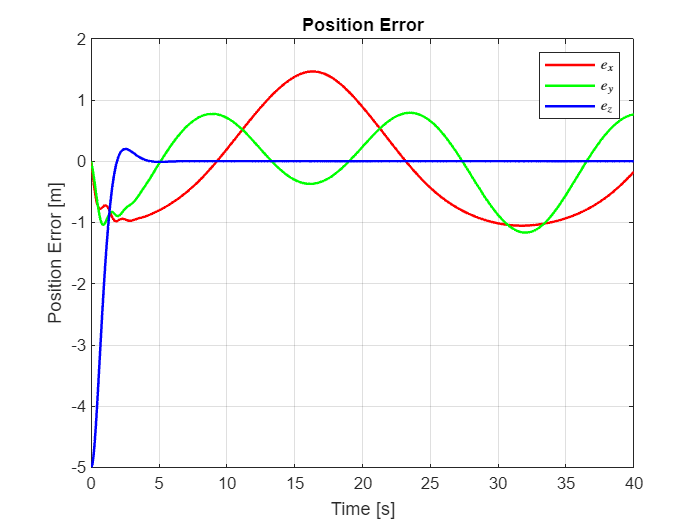

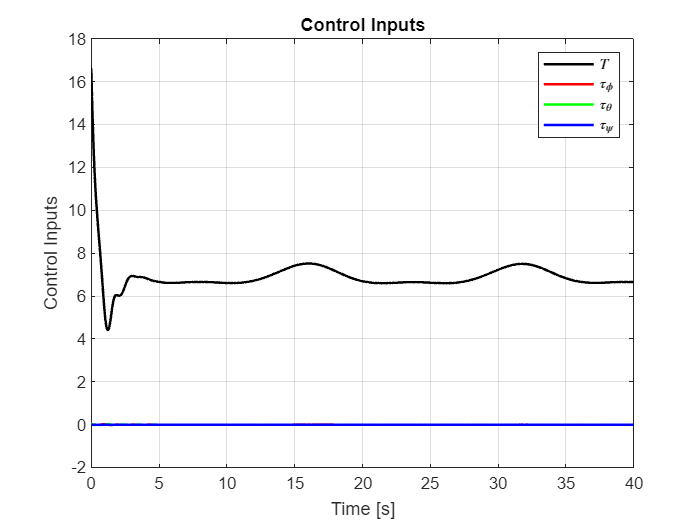

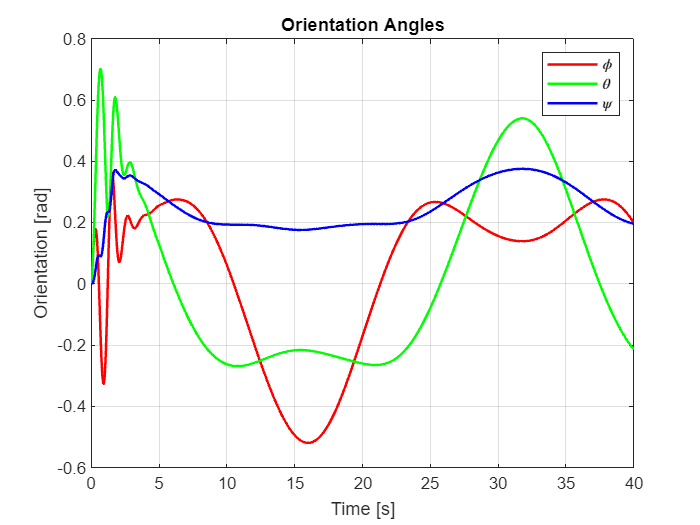

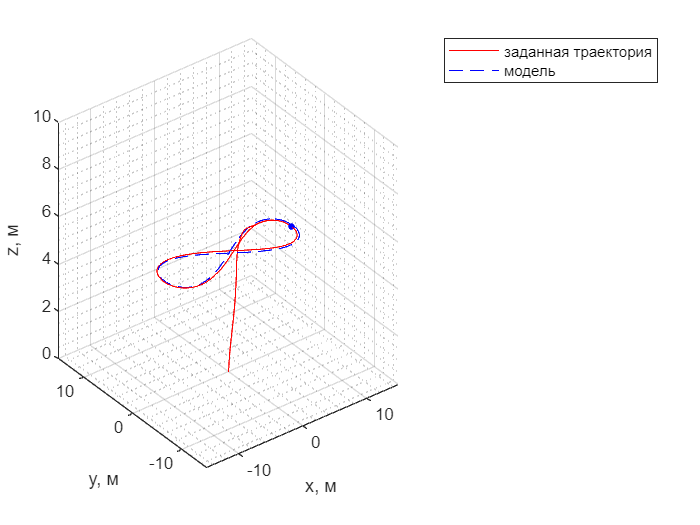

LQR_2_X = {};
LQR_2_Y = {};
LQR_2_Z = {};
for i=1:ITERATIONS
    C_drag = C_drag_arr(i);
    c_a = c_a_arr(i);
    c_b = c_b_arr(i);
    c_d = c_d_arr(i);
    time_model=time_model_arr(i);
    initQuadrotorData(c_a,c_b,c_d,C_drag);
    Simulation = sim('LQR_2_QuadrotorModel.slx');
    %Simulation = sim('model_for_testing_errors.slx');
    f = figure;
    plot3(Simulation.x.Data, Simulation.y.Data, Simulation.z.Data, 'r');
    LQR_2_X{i} = Simulation.x.Data;
    LQR_2_Y{i} = Simulation.y.Data;
    LQR_2_Z{i} = Simulation.z.Data;

    hold on
    plot3(Simulation.trajectory.Data(1,:),Simulation.trajectory.Data(2,:),Simulation.trajectory.Data(3,:),'b--')
    %plot3(Simulation.x1.Data, Simulation.y1.Data, Simulation.z1.Data, 'g--');
    if Mode==1
        xlim([-15, 15])
        ylim([-15, 15])
        zlim([0, 10])
    else
        xlim([-1, 21])
        ylim([-21, 1])
        zlim([0, 6])
    end
    grid on
    grid minor
    scatter3(Simulation.x.Data(end), Simulation.y.Data(end), Simulation.z.Data(end),15,'filled', 'b')
    xlabel("x, м")
    ylabel("y, м")
    zlabel("z, м")
    legend({"заданная траектория", "модель"})
    
    grid on
    ax = gca;
    X = Simulation.X.Data;
    Xd = squeeze(Simulation.trajectory.Data)';
    U = Simulation.U.Data;
    t = Simulation.U.Time;
    Qm = Qc(1:3, 1:3);
    Rm = Rc;
    metrics = evaluateTrajectoryTrackingMetrics(X, Xd, U, t, Qm, Rm);
    pref =  prefixes{i};
    metrics.name = "LQR_2_"+string(pref);
    results = [results; metrics];
    plotQuadrotorData(X, Xd, U, t, LQR_2_path, pref)
    ax.GridColor = [0, 0, 0];  % [R, G, B]
    
end

Model.StateFcn is OK.
Model.OutputFcn is OK.
Analysis of user-provided model, cost, and constraint functions complete.



Квадратичный критерий J = 2715.3242

--- Оценка слежения за траекторией ---
MAE (r_x, r_y, r_z): 0.2383, 0.1719, 0.0844
RMSE (r_x, r_y, r_z): 0.2963, 0.2050, 0.5367
MSE (r_x, r_y, r_z): 0.0878, 0.0420, 0.2880
Mean Error (r_x, r_y, r_z): -0.0006, 0.0110, -0.0521
Перерегулирование (%): 287.71, 218.76, 11.19


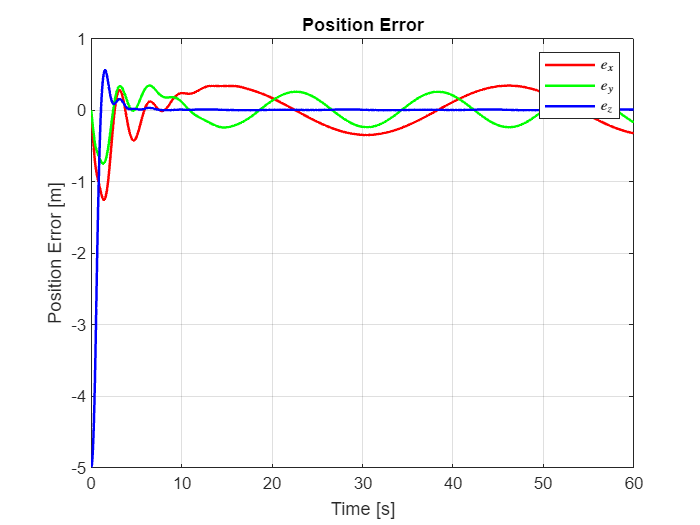

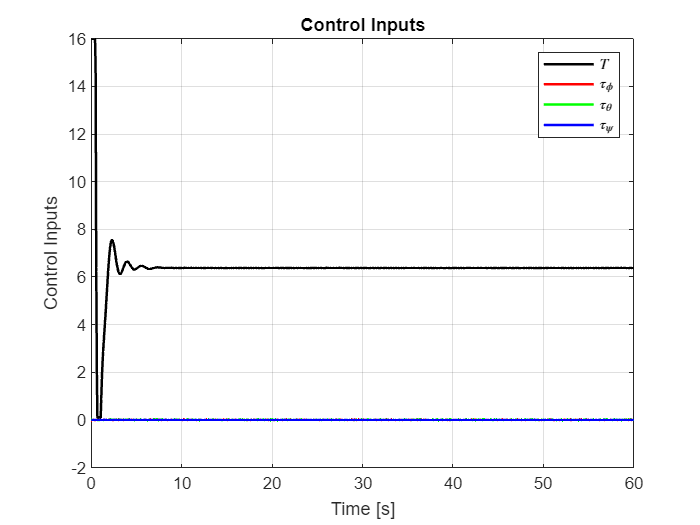

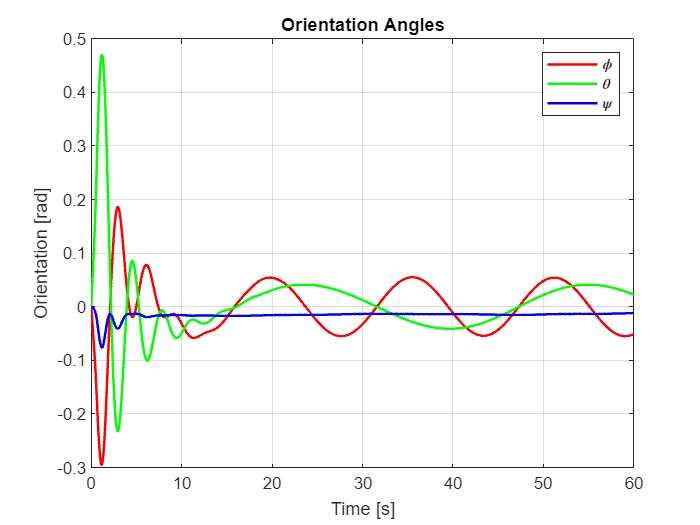

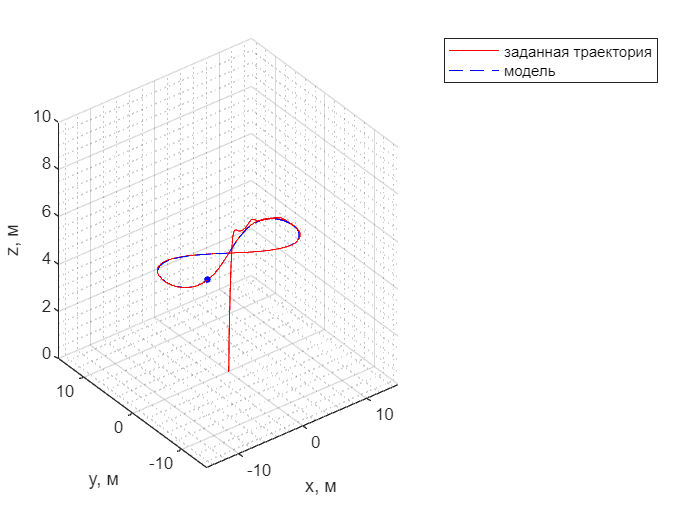

Model.StateFcn is OK.
Model.OutputFcn is OK.
Analysis of user-provided model, cost, and constraint functions complete.



Квадратичный критерий J = NaN

--- Оценка слежения за траекторией ---
MAE (r_x, r_y, r_z): 0.3198, 0.2253, 0.1051
RMSE (r_x, r_y, r_z): 0.3896, 0.2639, 0.5508
MSE (r_x, r_y, r_z): 0.1518, 0.0696, 0.3034
Mean Error (r_x, r_y, r_z): -0.0083, 0.0030, -0.0621
Перерегулирование (%): 287.62, 216.01, 12.92


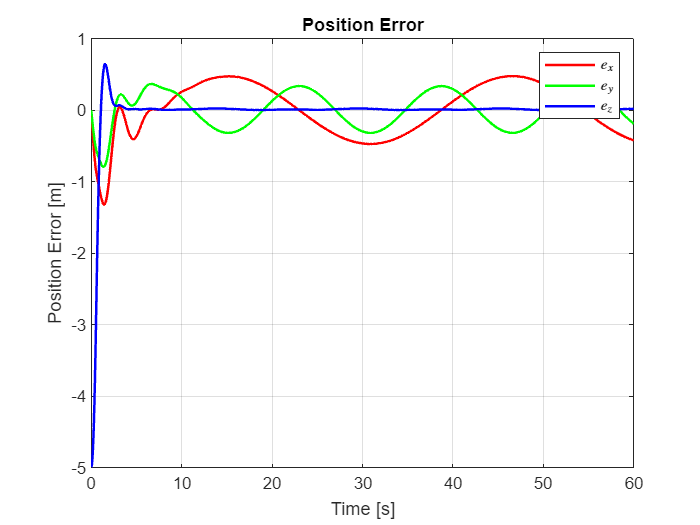

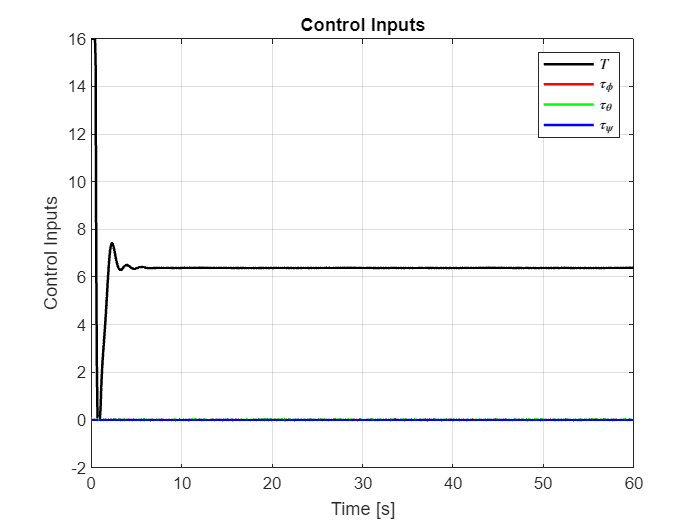

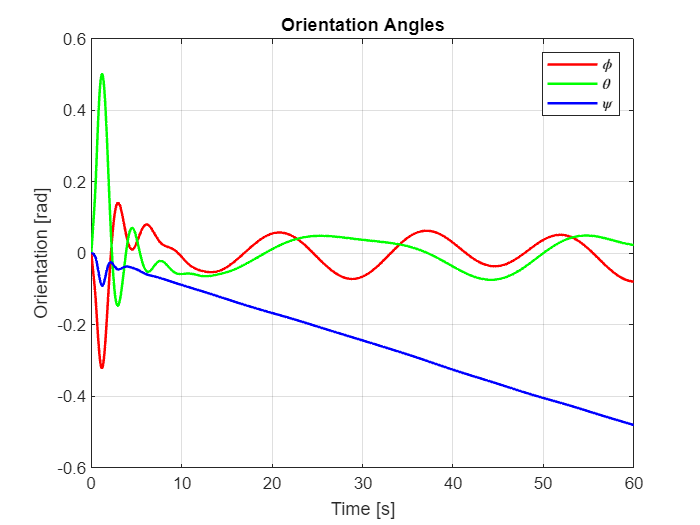

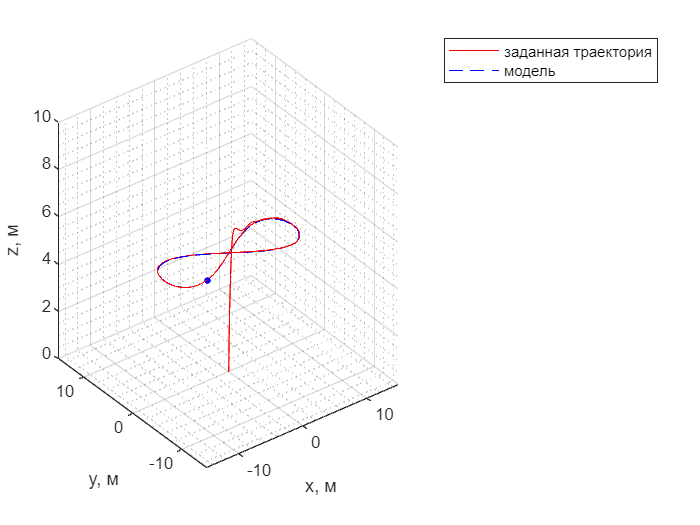

Model.StateFcn is OK.
Model.OutputFcn is OK.
Analysis of user-provided model, cost, and constraint functions complete.



Квадратичный критерий J = NaN

--- Оценка слежения за траекторией ---
MAE (r_x, r_y, r_z): 1.0710, 0.7410, 0.5630
RMSE (r_x, r_y, r_z): 1.2029, 0.8450, 0.8298
MSE (r_x, r_y, r_z): 1.4470, 0.7140, 0.6885
Mean Error (r_x, r_y, r_z): -0.1198, -0.0629, 0.3359
Перерегулирование (%): 292.39, 225.98, 28.55


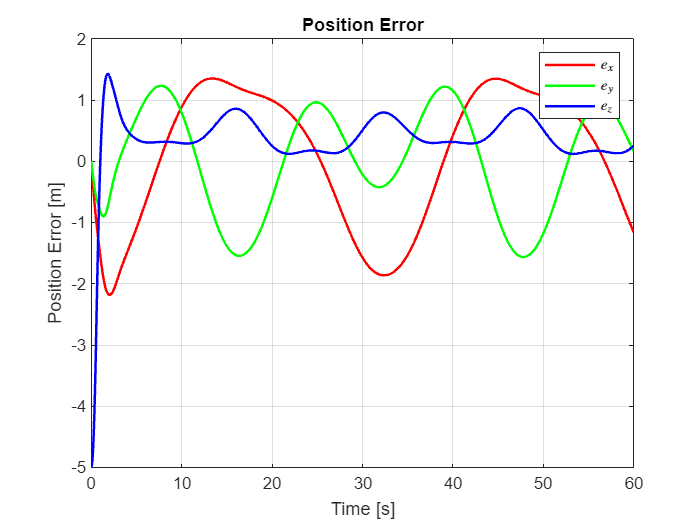

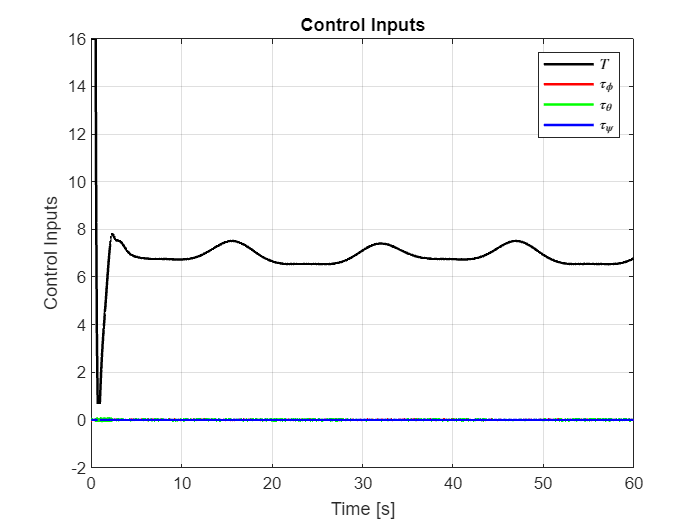

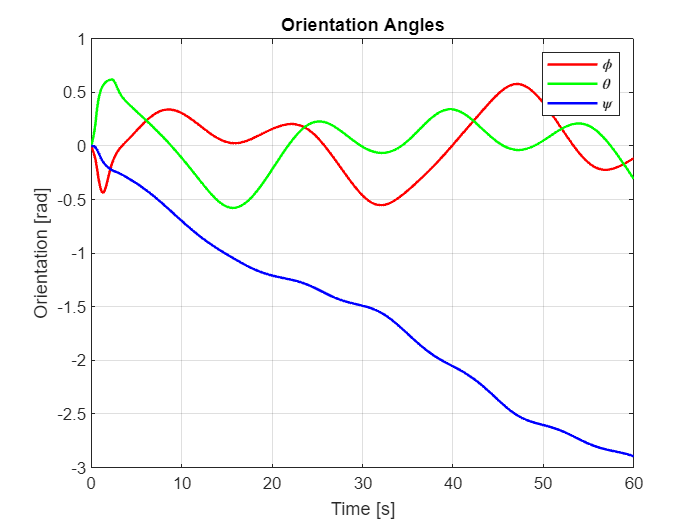

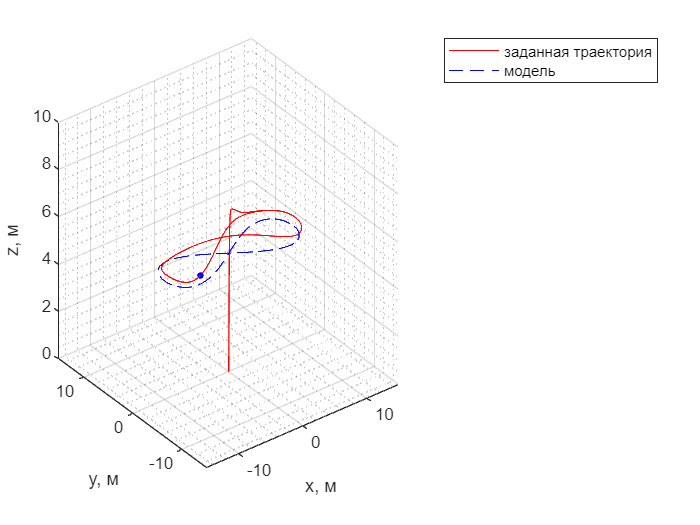

%return

params = struct();
params.N = 10;                     % горизонт предсказания
params.dt = 0.05;                  % шаг дискретизации, например 50 мс
params.alpha = 0.1;                % шаг градиентного спуска
params.max_iters = 10;            % количество итераций оптимизации

% Физические параметры квадрокоптера
params.m = m;                    % масса (кг)
params.g = g;                   % ускорение свободного падения
params.Ix = Ix;                  % моменты инерции
params.Iy = Iy;
params.Iz = Iz;

% Ограничения на управление
params.umin = [0; -0.1; -0.1; -0.1];  % минимальные значения [T; tau_phi; tau_theta; tau_psi]
params.umax = [16; 1; 1; 11];   % максимальные значения

u_nominal = [m*g; 0; 0; 0];  % держит квадрокоптер в воздухе
U_ref  = repmat(u_nominal', params.N, 1);  % [N x 4]\

N = params.N;
MPC_1_X = {};
MPC_1_Y = {};
MPC_1_Z = {};
for i=1:ITERATIONS
    C_drag = C_drag_arr(i);
    c_a = c_a_arr(i);
    c_b = c_b_arr(i);
    c_d = c_d_arr(i);
    initQuadrotorData(c_a,c_b,c_d,C_drag);
    time_model=time_model_arr(i);
    
    SimulationMPC = sim('MPC_1_QuadrotorModel.slx');
    %Simulation = sim('model_for_testing_errors.slx');
    f = figure;
    plot3(squeeze(SimulationMPC.x.Data), squeeze(SimulationMPC.y.Data), squeeze(SimulationMPC.z.Data), 'r');
    MPC_1_X{i} = squeeze(SimulationMPC.x.Data);
    MPC_1_Y{i} = squeeze(SimulationMPC.y.Data);
    MPC_1_Z{i} = squeeze(SimulationMPC.z.Data);
    hold on
    Xd = squeeze(SimulationMPC.trajectory.Data)';
    plot3(Xd(:,1),Xd(:,2),Xd(:,3),'b--')
    %plot3(Simulation.x1.Data, Simulation.y1.Data, Simulation.z1.Data, 'g--');
    if Mode==1
        xlim([-15, 15])
        ylim([-15, 15])
        zlim([0, 10])
    else
        xlim([-1, 21])
        ylim([-21, 1])
        zlim([0, 6])
    end
    grid on
    grid minor
    scatter3(squeeze(SimulationMPC.x.Data(end)), squeeze(SimulationMPC.y.Data(end)), squeeze(SimulationMPC.z.Data(end)),15,'filled', 'b')
    xlabel("x, м")
    ylabel("y, м")
    zlabel("z, м")
    legend({"заданная траектория", "модель"})
    
    grid on
    ax = gca;
    X = squeeze(SimulationMPC.X.Data)';
    U = squeeze(SimulationMPC.U.Data);
    t = SimulationMPC.U.Time;
    Qm = Qc(1:3, 1:3);
    Rm = Rc;
    metrics = evaluateTrajectoryTrackingMetrics(X, Xd, U, t, Qm, Rm);
    pref =  prefixes{i};
    metrics.name = "MPC_1_"+string(pref);
    results = [results; metrics];
    plotQuadrotorData(X, Xd, U, t, MPC_1_path, pref)
    ax.GridColor = [0, 0, 0];  % [R, G, B]
    
end

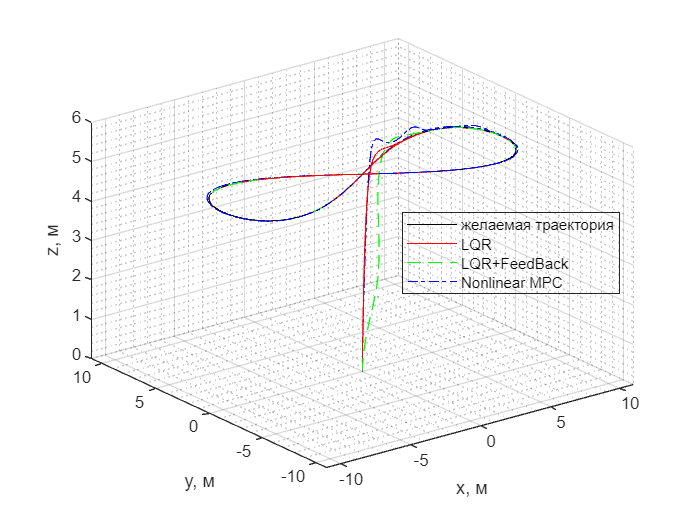

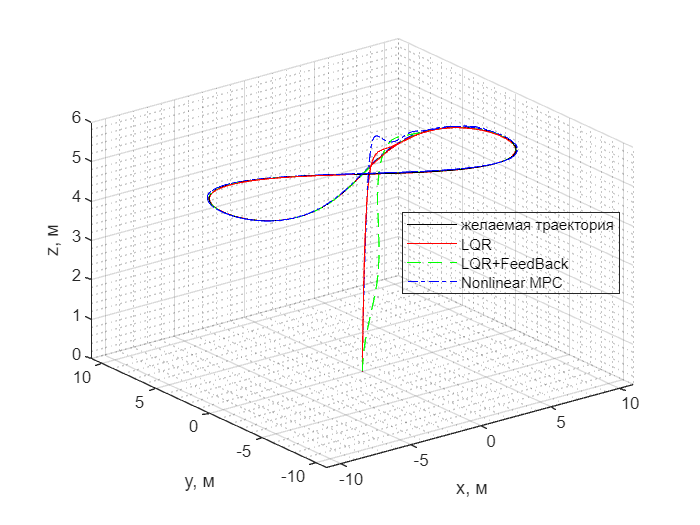

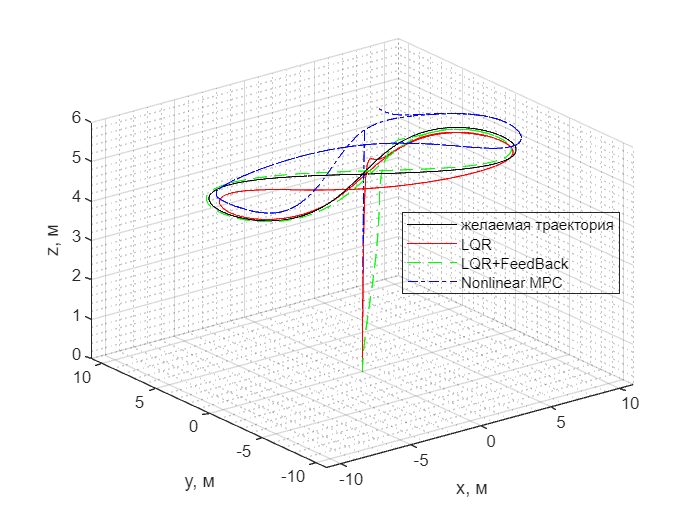

for i=1:ITERATIONS
    f = figure;
    plot3(Xd(:,1),Xd(:,2),Xd(:,3),'Color','black')
    hold on
    %LQR 1
    plot3(LQR_1_X{i}, LQR_1_Y{i}, LQR_1_Z{i}, 'r');
    %LQR 2
    plot3(LQR_2_X{i}, LQR_2_Y{i}, LQR_2_Z{i}, 'g--');
    % MPC
    plot3(MPC_1_X{i}, MPC_1_Y{i}, MPC_1_Z{i}, 'b-.');

   
    if Mode==1
        xlim([-11, 11])
        ylim([-11, 11])
        zlim([0, 6])
    else
        xlim([-1, 21])
        ylim([-21, 1])
        zlim([0, 6])
    end
    grid on
    grid minor
    %scatter3(Simulation.x.Data(end), Simulation.y.Data(end), Simulation.z.Data(end),15,'filled', 'b')
    xlabel("x, м")
    ylabel("y, м")
    zlabel("z, м")
    legend({"желаемая траектория", "LQR", "LQR+FeedBack", "Nonlinear MPC"},'Location', 'east')
    %legend boxoff;                   % убрать рамку
    set(legend, 'Color', 'none');    % прозрачный фон
    grid on
    ax = gca;
    ax.GridColor = [0, 0, 0];
    saveas(f, fullfile(base_path, ['3d/' prefixes{i} '.png']));
end


results_table = struct2table(results);

writetable(results_table, 'metrics_summary.csv');

% Или показываем в консоли
disp(results_table);

                  MAE                              RMSE                               MSE                                   MeanError                      J               OvershootPercent                       name            
    _______________________________    _____________________________    ________________________________    _________________________________________    ______    ________________________________    ___________________________

     1.0144     0.65453      0.1829     1.1406     0.7385    0.86303       1.301     0.54539     0.74482       -0.21373       0.023576       -0.17275    2577.3      1.0632      447.43      3.9016    "LQR_1_eight_no_ressist"   
     1.0954     0.69937     0.18316     1.2297    0.78876    0.86249      1.5122